Submission #2 after review of first submission. Utilized second order forward finite difference differentiation for the first and last point. Previously only utilized first order.

%rate of cooling problem
% Define the time and temperature data
t = [0, 5, 10, 15, 20, 25];
T = [80, 44.5, 30.0, 24.1, 21.7, 20.7];
%water temp
Ta = 20;
%array
dTdt = zeros(size(T));

%Differentiate with finite difference method
for i = 1:length(t)
    if i == 1  %changed for second submission, utilize [second order] forward
                %finite difference per HW submission 1 review.
        dTdt(i) = (-3*T(i) + 4*T(i+1) - T(i+2)) / (t(i+2) - t(i));
    elseif i == length(t)  % [second order] backwards difference implementation
        dTdt(i) = (3*T(i) - 4*T(i-1) + T(i-2)) / (t(i) - t(i-2));
    else  % Central difference at interior points
        dTdt(i) = (T(i+1) - T(i-1)) / (t(i+1) - t(i-1));
    end
end

%rate of cooling
dTdt

dTdt =   -9.199999999999999  -5.000000000000000  -2.040000000000000  -0.830000000000000  -0.340000000000000  -0.060000000000000


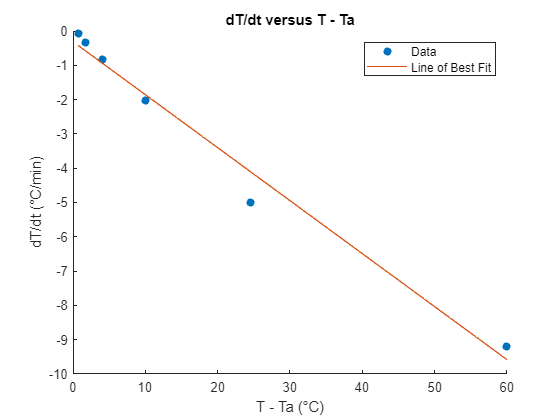


% Calculate T-Ta
T_diff = T - Ta;

% Plot 
figure;
scatter(T_diff, dTdt, 'filled');
xlabel('T - Ta (°C)');
ylabel('dT/dt (°C/min)');
title('dT/dt versus T - Ta');

%polyfit linear regression as requered in problem 23
p = polyfit(T_diff, dTdt, 1);
hold on;
x = linspace(min(T_diff), max(T_diff));
y = polyval(p, x);
plot(x, y);
legend('Data', 'Line of Best Fit');